# ** Simulações de antenas *****microstrip***** com células SRR nas laterais para 5G**

`por Renan Machado`

Este é um *live script* em MatLAB que visa construir um *dataset* de simulações de antenas com metamateriais para treinar modelos preditivos de *machine learning*. Os parâmetros dos metamateriais, como comprimento da célula, disposição do arranjo, e outros, serão variados em uma faixa de valores adequados, procurando respeitar as referências oferecidas pela literatura. O *software* utilizado para as simulações eletromagnéticas é o **CST Studio Lite©**, utilizando o módulo **Microwave Studio**. Para o controle automatizado do software, será utilizada a API desenvolvida por Symeon Symeonidis, Stefanos Tsantilas e Stelios Mitilineos, tendo o código fonte e a documentação disponíveis [aqui](https://github.com/simos421/CST-MATLAB-API). A API original foi modificada e está disponível no repositório.

## Inicialização do CST

Para correta utilização da API, antes é necessário adicionar seu código fonte ao *path*, dessa forma:

addpath(genpath('CST-MATLAB-API-master'));

Para iniciar a aplicação do CST, utilizamos o seguinte comando:

cst = actxserver('CSTStudio.application');

Agora, com o CST aberto, podemos inicializar o Microwave Studio.

mws = cst.invoke('NewMWS');

Você deve ter na sua tela algo parecido como a figura abaixo.

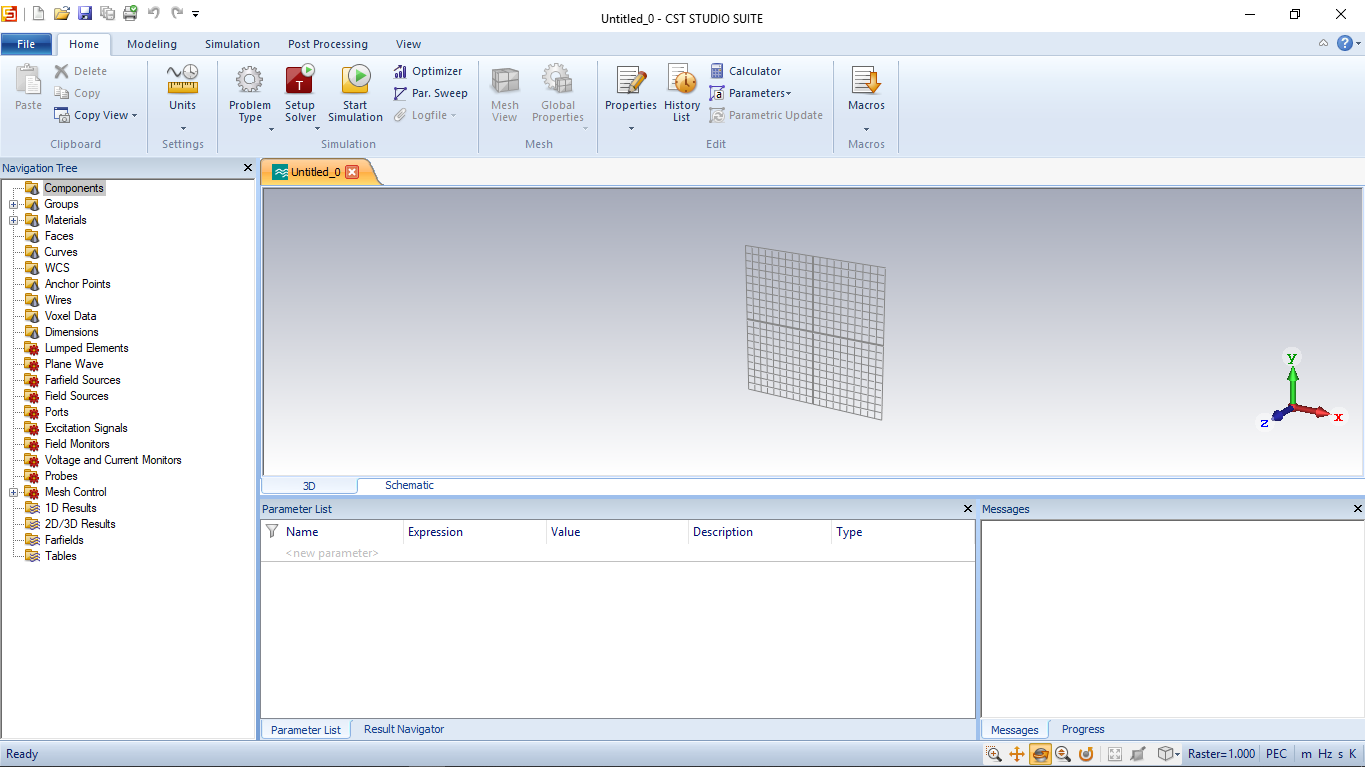

## Configurando o ambiente de simulação

Na MCW (*Mobile World Congress*) de 2019, o presidente da ANATEL, Leonardo de Morais, anunciou o leilão de 200 MHz na frequência de 3,5 GHz que serão destinados para implantação do 5G no Brasil. Aqui, a frequência será esse domínio reservado na frequência de 3.5GHz que a ANATEL anunciou. 

Inicialmente, precisamos definir as unidades padrão. É importante ressaltar que a **unidade de comprimento é micrometros** (1e-6 metros). Com isso, também é necessário definir o intervalo de frequência que será simulado, aqui serão simulados 3% da frequência central como limites inferior e superior. Assim, é possível inicializar a *mesh* e definir as condições de contorno.

fcenter = 3.5;
fmin = fcenter * 0.97

fmin = 3.3950

fmax = fcenter * 1.03

fmax = 3.6050

Em código:

CstDefineUnits(mws, 'um', 'GHz', 's', 'Kelvin', 'V', 'A', 'Ohm', 'S', 'PikoF', 'NanoH');
CstDefineFrequencyRange(mws, fmin, fmax);
CstMeshInitiator(mws);

A antena estará no espaço livre, então:

%Condições de contorno
Xmin = 'expanded open';
Xmax = 'expanded open';
Ymin = 'expanded open';
Ymax = 'expanded open';
Zmin = 'expanded open';
Zmax = 'expanded open';

CstDefineOpenBoundary(mws, fmin, Xmin, Xmax, Ymin, Ymax, Zmin, Zmax);

Em seguida, precisamos definir o material do fundo:

XminSpace = 0;
XmaxSpace = 0;
YminSpace = 0;
YmaxSpace = 0;
ZminSpace = 0;
ZmaxSpace = 0;

CstDefineBackroundMaterial(mws, XminSpace, XmaxSpace, YminSpace, YmaxSpace, ZminSpace, ZmaxSpace);

## Definição de materiais

Para a definição de materiais que serão utilizados nos componentes, é preciso definir as propriedades do material de acordo com a biblioteca do CST e fazer uma função em MatLAB com todas essas propriedades, juntamente com o nome do material. Somente depois disso é que podemos utilizar o nome do material no código. Na API, já temos funções para definir materiais como cobre e FR4 com perdas.

metal = CstCopperAnnealedLossy(mws)

metal = 'Copper (annealed)'

[dieletric, epsilon_r] = CstFR4lossy(mws)

dieletric = 'FR-4 (lossy)'

epsilon_r = 4.3000

Além disso, precisamos definir a altura da folha de metal (nesse caso, cobre).

t = 0.035*1e3; % in um (t from thickness)

## *Design* da antena base

Na criação do *dataset*, os metamateriais serão aplicados em uma antena base que possui bons parâmetros. Essa antena será projetada com base em toda a referência bibliográfica existente. No *design *de antenas, é necessário definir primariamente o material do substrato e a frequência de aplicação. A altura do substrato também precisa ser predefinida com antecedência. A bibliografia sugere uma escolha entre $0,03\lambda$ e $0,5\lambda$, tendo uma preferência por substratos mais finos por resultarem em uma melhor eficiência de radiação. Para esse projeto:

h = 1700; % in um (1e-6 meters)

As variáveis associadas a geometria de uma antena *microstrip* são essas mostradas na figura abaixo. 

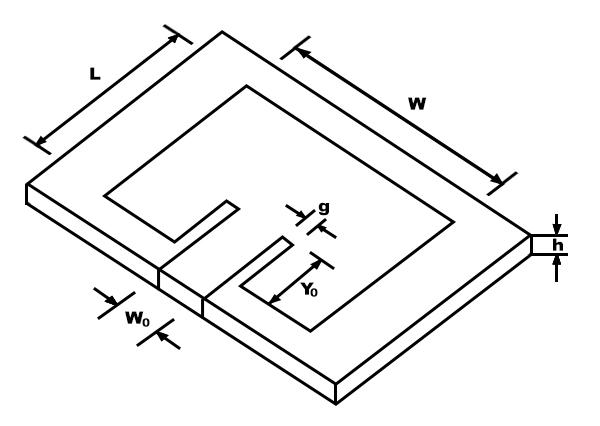

Para uma obtermos uma boa eficiência de radiação, (BALANIS, 2005) nos dá que:


$$W=\frac{c}{2f_r }\sqrt{\;\frac{2}{{\epsilon \;}_r +1}}$$


W = 0.9*3e8/(2*fcenter*1e9)*sqrt(2/(epsilon_r+1))*1e6 % in um

W = 2.3694e+04

Antes de definirmos $L$, precisamos calcular a constante dielétrica efetiva da antena, já que algumas ondas viajam no substrato e algumas no ar. Segundo (BALANIS, 2005):


$$\epsilon_{\mathrm{reff}} =\frac{\epsilon_r +1}{2}+\frac{\epsilon_r -1}{2}{\left(1+12\;\frac{h}{W}\right)}^{-\frac{1}{2}}$$


epsilon_reff = (epsilon_r+1)/2+((epsilon_r-1)/2).*(1+(12/W).*h).^(-1/2)

epsilon_reff = 3.8595

Agora que temos a constante dielétrica efetiva, calculamos o quão maior o patch aparenta ser do que realmente é através de:


$$\Delta L=0,412h\;\frac{\left(\epsilon_{\mathrm{reff}} +0,3\right)\left(\frac{W}{h}+0,264\right)}{\left(\epsilon_{\mathrm{reff}} -0,258\right)\left(\frac{W}{h}+0,8\right)}$$


delta_l = 0.412.*h.*((epsilon_reff+0.3).*(W./h+0.264))./((epsilon_reff-0.258).*(W./h+0.8))

delta_l = 779.4965

Finalmente, temos que:


$$L=\frac{c}{2f_r \sqrt{\epsilon_{\mathrm{reff}} }}-2\Delta L$$


l = 0.98.*3e5./(2*fcenter*sqrt(epsilon_reff))-2.*delta_l

l = 1.9820e+04

Por último, os parâmetros restantes normalmente são:


$$Y_0 =4h$$



$$g\approx 1000\;\mathrm{um}$$



$$W_0 =3,5g$$


Y0 = 4*h

Y0 = 6800

g = 1000;
W0 = 3.5*g

W0 = 3500

Para refletir essas medidas no CST, usamos:

DrawMicrostripAntenna(mws, W, l, t, h, Y0, W0, g, metal, dieletric);
DrawPort(mws, W, l, t, h, W0);

## Simulação da antena base

Vamos agora definir o monitor de campo distante (*farfield*) na frequência de ressonância. Aqui um passo manual precisa ser dado, já que os *templates* de pós-processamento são uma *feature* relativamente nova, o controle VBA desse componente não está disponível na API. 

Para criar esse *template*, adicione um *breakpoint* (clicando sobre o número da linha) na linha comentada para parar a execução do código. Abra o CST no menu superior, selecione a aba ***Post Processing > Result Templates > Template Based Post Processing***. Na primeira caixa, selecione ***Farfield and Antenna Properties*** e na segunda ***Farfield Result***. Selecione o *template ****Max Gain over Frequency*** e renomeie-o para ***Gain***, clicando duas vezes sobre o item. Após isso, clique em ***Close*** e continue com a execução do código.

Não se esqueça de definir o caminho onde serão exportados os resultados modificando a variável *base_path*.

base_path = 'C:\Users\Renan\results'

base_path = 'C:\Users\Renan\results'


CstDefineFarfieldMonitor(mws,strcat('farfield (f=',num2str(fcenter),')'), fcenter);

%Create template for Gain vs Frequency (name it Gain)

CstDefineTimedomainSolver(mws,-40);

ExportResults(mws, base_path, 0, W, l, t, h, Y0, W0, g);

CstSaveProject(mws,strcat(base_path, '\0\simulacao.cst'));
CstQuitProject(mws);

## Intervalo de valores para a célula metamaterial

As variáveis associadas a geometria de uma célula metamaterial quadrada são mostradas na figura abaixo.

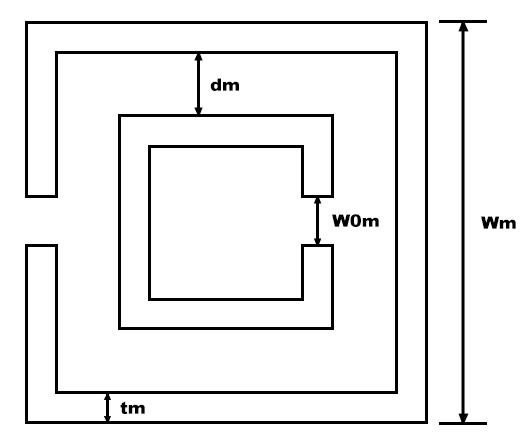

De acordo com a literatura, as células metamateriais apresentam suas características DNG (Double Negative) para intervalos de:


$$0,025\lambda \le W_m \le \frac{\lambda }{4}$$



$$t_m \approx 0,1W_m$$



$$1,9\times {10}^{-3} \lambda \le W_{0m} \le 7,6\times {10}^{-3} \lambda$$



$$0,9\times {10}^{-3} \lambda \le d_m \le 5,7\times {10}^{-3} \lambda$$


Alguns intervalos estão em função do comprimento de onda $\lambda$, de forma que:


$$\lambda =\frac{c}{f}$$


lambda = 3e5./fcenter % in um (1e-6 m)

lambda = 8.5714e+04

n_Wm = 5;

Wm_min = 0.025*lambda;
Wm_max = 1/4*lambda;
Wm_step = (Wm_max-Wm_min)/(n_Wm-1);
Wm = Wm_min:Wm_step:Wm_max

Wm = 	1.0e+04 *

    0.2143    0.6964    1.1786    1.6607    2.1429


tm = 0.1.*Wm

tm = 	1.0e+03 *

    0.2143    0.6964    1.1786    1.6607    2.1429


n_W0m = 4;

W0m_min = 1.9e-3*lambda;
W0m_max = 7.6e-3*lambda;
W0m_step = (W0m_max-W0m_min)/(n_W0m-1);
W0m = W0m_min:W0m_step:W0m_max

W0m =   162.8571  325.7143  488.5714  651.4286


n_dm = 4;

dm_min = 0.9e-3*lambda;
dm_max = 5.7e-3*lambda;
dm_step = (dm_max-dm_min)/(n_dm-1);
dm = dm_min:dm_step:dm_max

dm =    77.1429  214.2857  351.4286  488.5714


Até agora, o número total de simulações é:

n_sim = n_Wm*n_W0m*n_dm

n_sim = 80

## Intervalo de valores pro arranjo

Primeiramente, vamos trabalhar com arranjos ímpares de colunas, ou seja:

rows = 3:2:7;

A distância em X entre o arranjo e o *patch* $X_a$ (contando da borda) será:


$$0\le X_a \le \left(\frac{W}{2}-\frac{W_m }{2}\right)$$


n_Xa = 2;

Xa = zeros(length(Wm), n_Xa);
for i = 1:length(Wm)
    Xa_min = 0;
    Xa_max = W/2-Wm(i)/2;
    Xa_step = (Xa_max-Xa_min)/(n_Xa-1);
    
    Xa(i,:) = Xa_min:Xa_step:Xa_max;
end
Xa = Flat(Xa)

Xa = 	1.0e+04 *

         0
    0.1133
    0.3544
    0.5954
    0.8365
    1.0776


A distância em Y entre as células do arranjo $Y_a$ (contando da borda) será:


$$W_m \le Y_a \le \left(\frac{4L}{\textrm{rows}-1}-W_m \right)$$


n_Ya = 2;

Ya = zeros(length(Wm), n_Ya);
for i = 1:length(Wm)
    Ya_min = Wm(i);
    Ya_max = 4*l/(min(rows) - 1)-Wm(i);
    Ya_step = (Ya_max-Ya_min)/(n_Ya-1);
    
    Ya(i,:) = Ya_min:Ya_step:Ya_max;
end
Ya = Flat(Ya);
Ya = Ya(Ya>=0) % get only positive values

Ya = 	1.0e+04 *

    0.2143
    0.6964
    1.1786
    1.6607
    1.8211
    2.1429
    2.3032
    2.7854
    3.2675
    3.7497


## Simulação

Para verificar quais combinações de geometria são possíveis, é necesário fazer uma verificação 1:1.

% Unit cell vars
%   Wm and tm
%   W0m
%   dm

possible_geometry = [];
count = 1;
for wm = 1:length(Wm)
    for w0m = 1:length(W0m)
        for Dm = 1:length(dm)
            
            % Cells line-up vars
            %   Xa
            %   Ya
            
            for row = 1:length(rows)
                for xa = 1:length(Xa)
                    if (xa <= W/2 - Wm(wm)/2) % means that line-up doesn't extend beyond substrate width
                        for ya = 1:length(Ya)
                            if(ya <= 4*l/(rows(row)-1) - Wm(wm)) % means that line-up doesn't extend beyond substrate height
                                possible_geometry(count, :) = [Wm(wm) tm(wm) W0m(w0m) dm(Dm) rows(row) Xa(xa) Ya(ya)];
                                count = count + 1;
                            end
                        end
                    end
                end
            end
        end
    end
end

fprintf(['Número de simulações: %d\n' ...
    'Tempo estimado de conclusão: %.0f dias'], count, 3*count/60/24);

Número de simulações: 11521
Tempo estimado de conclusão: 24 dias

Para construir os arranjos possíveis, devemos:

count = 1;

for i = 1:length(possible_geometry)
    
    mws = cst.invoke('OpenFile', strcat(base_path, '\0\simulacao.cst'));
    
    CstDefineFrequencyRange(mws, fmin, fmax);
    CstMeshInitiator(mws);
    
    CstDefineOpenBoundary(mws, fmin, Xmin, Xmax, Ymin, Ymax, Zmin, Zmax);
    
    CstDefineBackroundMaterial(mws, XminSpace, XmaxSpace, YminSpace, YmaxSpace, ZminSpace, ZmaxSpace);
    
    metal = CstCopperAnnealedLossy(mws);
    [dieletric, epsilon_r] = CstFR4lossy(mws);
    
    DrawPort(mws, W, l, t, h, W0);
    
    for side = [-1 1]
        for cell = 1:possible_geometry(i,5)
            
            Wm = possible_geometry(i,1);
            W0m = possible_geometry(i,3);
            dm = possible_geometry(i,4);
            tm = possible_geometry(i,2);
            hm = t+h;
            h0 = t;
            
            Xa = possible_geometry(i,6);
            Ya = possible_geometry(i,7);
            
            if cell == 1
                ya = 0;
            elseif mod(cell,2) == 0
                ya = (cell/2)*(Ya+Wm);
            else
                ya = (-1)*((cell-1)/2)*(Ya+Wm);
            end
            
            xa = (W/2+Xa+Wm/2)*side;
            
            DrawSquareSRR(mws,Wm,W0m,dm,tm,hm,h0,metal,cell*side,xa,ya)
        end
    end
    
    CstDefineFarfieldMonitor(mws,strcat('farfield (f=',num2str(fcenter),')'), fcenter);
   
    CstDefineTimedomainSolver(mws,-40);
    
    ExportResultsMeta(mws, 'C:\Users\Renan\results', count, Wm,W0m,dm,tm,hm,h0,cell,Xa,Ya);
    
    CstSaveAsProject(mws,strcat('C:\Users\Renan\results\',num2str(count),'\simulacao.cst'));
    CstQuitProject(mws);
    
    count = count + 1;
end